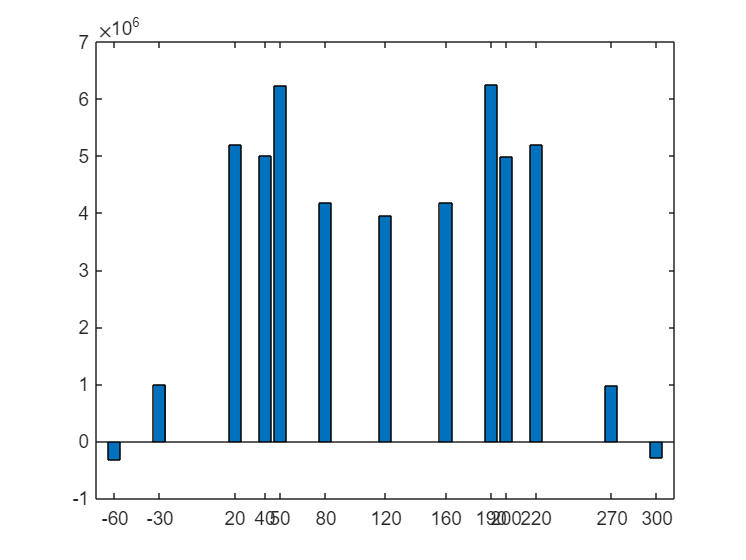

bar(obj.XCoordOfPz,data_container.Data.Pz_solved)

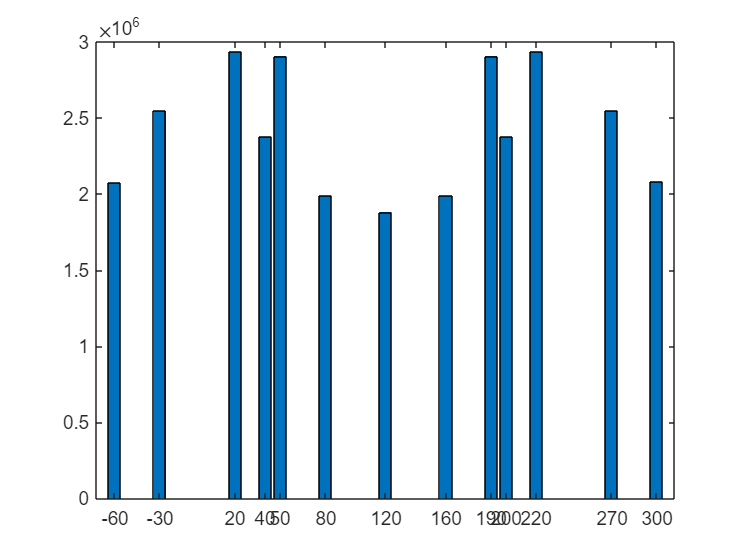

bar(obj.XCoordOfPz,Pz_final)

force

force = 1.0e+06 *

    0.0502    0.0502    0.7099    0.7099    2.8434    2.8434    2.5755    2.5755    3.7587    3.7587    2.1360    2.1360    2.0308    2.0308    2.1373    2.1373    3.7661    3.7661    2.5739    2.5739    2.8466    2.8466    0.7022    0.7022    0.0717    0.0717


INodeX;
INodeY;
INodeZ;
JNodeX;
JNodeY;
JNodeZ;
L;
X_elem;
W;

force_vertical = force.*abs(JNodeZ-INodeZ)./(L);
i = 1;
index = abs(X_Pz(i)-X_elem)<=1e-3;
Pz_solved(i) = sum(force_vertical(index) - L(index).*W(index)/2);